l0 = 10;
k = 20;
L = [
    1 0 0 -1 0 0;
    0 1 0 0 -1 0;
    0 0 1 0 0 -1;
    -1 0 0 2 0 0;
    0 -1 0 0 2 0;
    0 0 -1 0 0 2;
    ];
% J is wrong, think about how many constraints?
J = [
    1 0 0 0 0 0;
    0 1 0 0 0 0;
    0 0 1 0 0 0;
    -1 0 0 1 0 0;
    0 -1 0 0 1 0;
    0 0 -1 0 0 1;
    ];

x1 = [0;-5;0];
x2 = [0;10;0];

X0 = [x1;x2];
x1 = X0(1:3)

x1 =      0
    -5
     0


x2 = X0(4:6)

x2 =      0
    10
     0




h = 1/60;

M = 0.2*eye(6);
M_inv = inv(M);

V0 = zeros(6,1);

Y = X0+V0*h;

L = L*20;
J = J*20;

d = x1-x2;
d = d / norm(d) * l0;
D = [d;x2];

A = M + h*h*L;

b = M*Y+h*h*(J*D );

% we have two constraints:
% 1. 1 spring
% 2. 1 attach point

X1 = A\b

X1 =          0
   -4.8683
         0
         0
    9.8719
         0


V1 = (X1 -X0) / h

V1 =          0
    7.9004
         0
         0
   -7.6868
         0


% iterative
step = 100;
V = zeros(1,step);
L = zeros(1,step);
E = zeros(1,step);
X = zeros(1,step);

for i=1:step
    Y = X0+V0*h;
    d = x1-x2;
    d = d / norm(d) * l0;
    D = [d;x2];
    b = M*Y+h*h*(J*D);
    X1 = A\b;
    V1 = (X1 -X0) / h;
    X0 = X1;
    x1 = X0(1:3);
    x2 = X0(4:6);
    l1 = norm(x1-x2);
    vnorm = norm(V1);
    E_current = 0.5*0.2*vnorm*vnorm + 0.5*k*(l1-l0)*(l1-l0);
    V(i) = V1(2);
    L(i) = l1;
    E(i) = E_current;
    X(i) = X1(2);
    V0 = V1;
end      

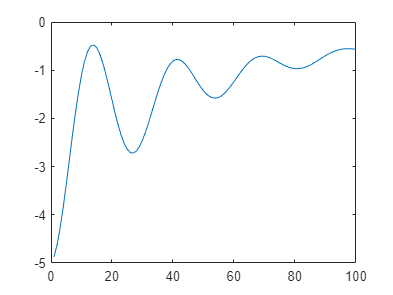

plot(X)

%plot(X)
%plot(V)
%plot(L)
%plot(E)

J = [
    1 0 0 0 0 0;
    0 1 0 0 0 0;
    0 0 1 0 0 0;
    -1 0 0 1 0 0;
    0 -1 0 0 1 0;
    0 0 -1 0 0 1;
    ]

J =      1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     1     0     0     0
    -1     0     0     1     0     0
     0    -1     0     0     1     0
     0     0    -1     0     0     1
